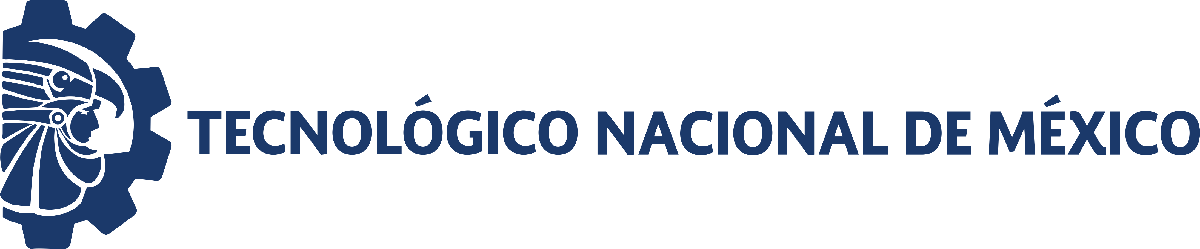                                 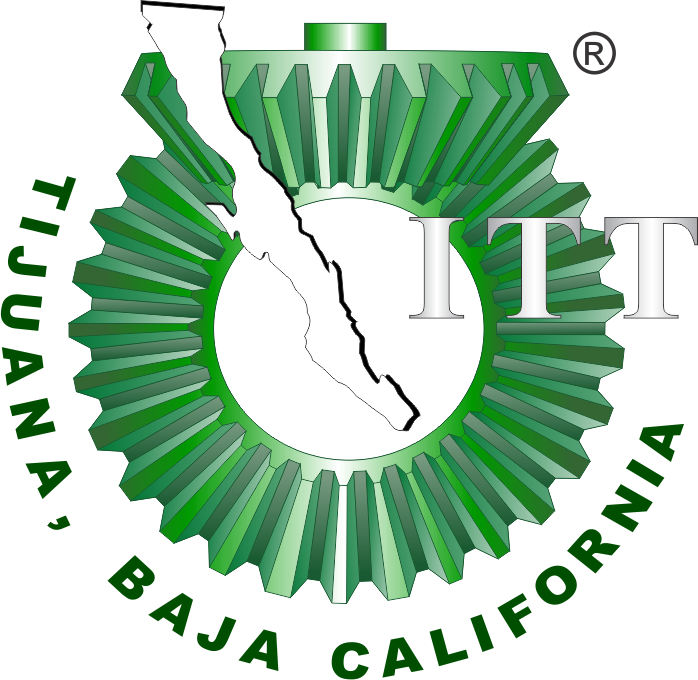

# Práctica 4: Modelo cardiovascular

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

## 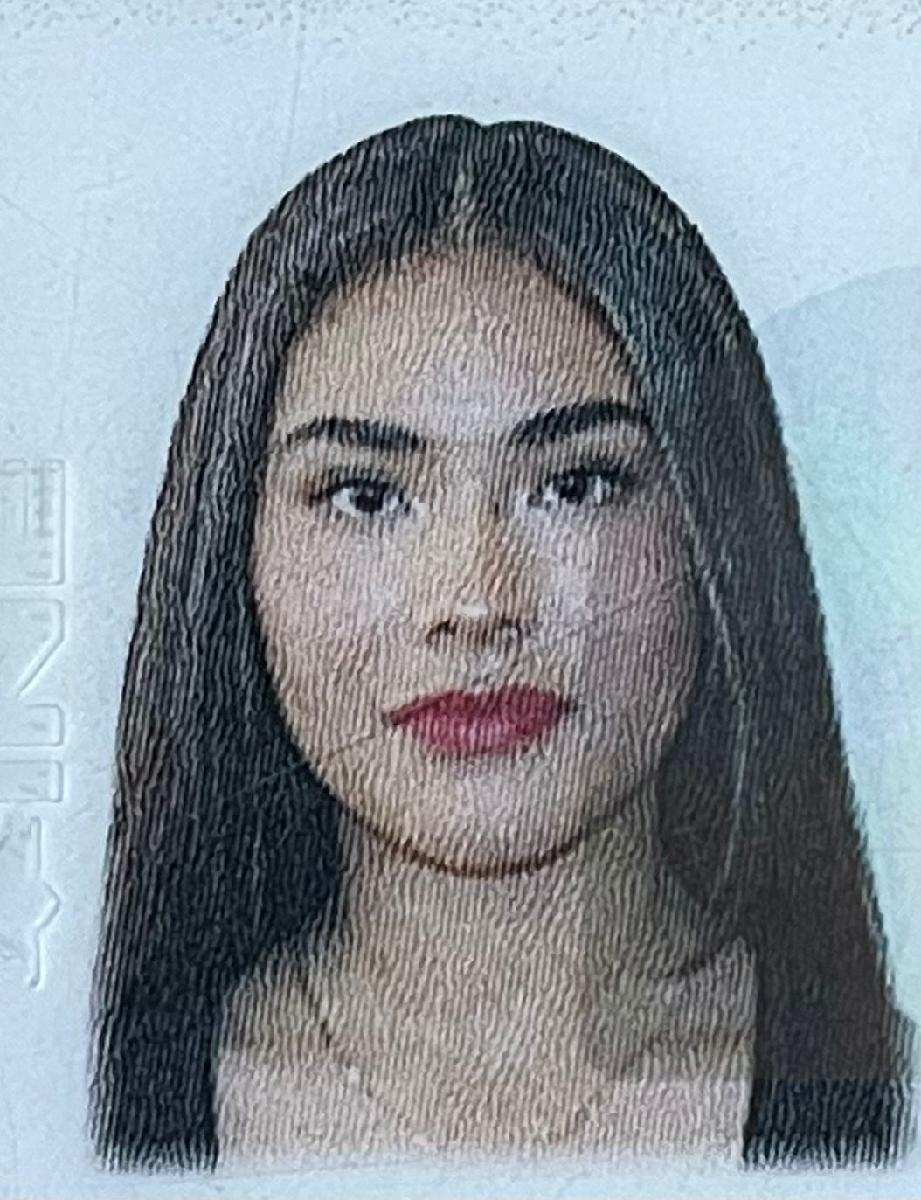

Nombre del alumno: **Karla Valeria Garcia Murillo**

Número de control: **22212385**

Correo institucional: **l22212385@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; warning('off','all')
tend = '10';
file = 'practica4' ;
open_system(file);
parameters.StopTime= tend;
parameters.Solver = 'ode23t';
parameters.MaxStep = '1E-3';
set_param('practica4/Ppa(t)','Minimum','-0.2');
set_param('practica4/Ppa(t)','Maximum','1');
set_param('practica4/Ppa(t)','Seed','106');
set_param('practica4/Ppa(t)','SampleTime','0.5');
x = sim(file,parameters);
writematrix(x.Ppa,'signal.xlsx')

## Lazo abierto

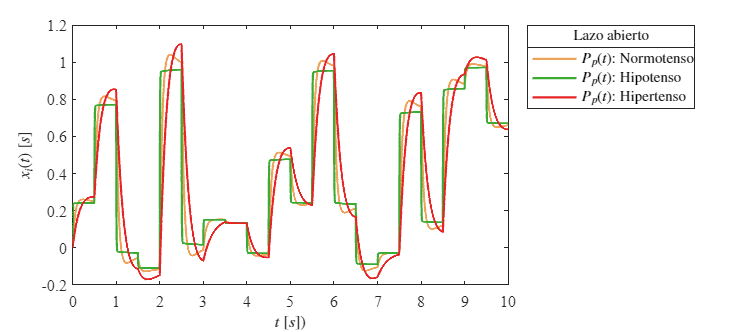


plotsignals(x.t,x.Pp0,x.Pp1,x.Pp2)

## Lazo cerrado

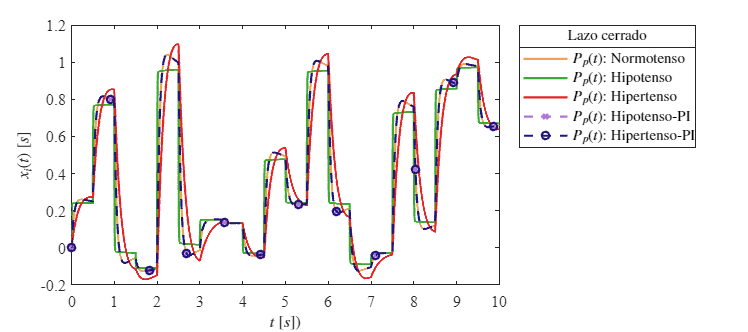


plotsignals1(x.t,x.Pp0,x.Pp1,x.Pp2,x.Pp3,x.Pp4)

## Función: Respuesta a las señales

function plotsignals(t,Pp0,Pp1,Pp2,Signal)
    set(figure(),"color","w")
    set(gcf,'units','centimeters','position',[1,1,18,8])
    set(gca,'FontName','Times New Roman','FontSize',11)
    hold on; grid off; box on;
    mycolors = [0.93,0.64,0.35;
                0.23,0.67,0.20;
                0.90,0.15,0.15;
                0.68,0.46,0.85;
                0.13,0.09,0.48;
                1.00,0.29,0.76];
    colororder(mycolors)

   
    
    p = plot(t,Pp0,'-',t,Pp1,'-',t,Pp2,'-',...
       'Linewidth',1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t));
    set(p(3), 'Linewidth',1.5)
    L = legend('$P_p(t)$: Normotenso','$P_p(t)$: Hipotenso', '$P_p(t)$: Hipertenso');
    set(L,'Interpreter','latex','FontSize',10,'Location','BestOutside','Box','On');
    title(L,['Lazo abierto'],'FontSize',10)

    xlabel('$t$ $[s]$)', 'Interpreter', 'latex', 'FontSize',11)
    ylabel('$x_i(t)$ $[s]$', 'Interpreter', 'latex', 'FontSize',11)

    xlim([0,10]); xticks(0:1:10);
    

    exportgraphics(gcf,['cv_lazoabierto.pdf'],'ContentType','vector')
    exportgraphics(gcf,['cv_lazoabierto.png'],'ContentType','vector')
end

function plotsignals1(t,Pp0,Pp1,Pp2,Pp3,Pp4,Signal)
    set(figure(),"color","w")
    set(gcf,'units','centimeters','position',[1,1,18,8])
    set(gca,'FontName','Times New Roman','FontSize',11)
    hold on; grid off; box on;
    mycolors = [0.93,0.64,0.35;
                0.23,0.67,0.20;
                0.90,0.15,0.15;
                0.68,0.46,0.85;
                0.13,0.09,0.48;
                1.00,0.29,0.76];
    colororder(mycolors)

   
    
    p = plot(t,Pp0,'-',t,Pp1,'-',t,Pp2,'-',t,Pp3,'--x',t,Pp4,'--o',...
       'Linewidth',1.5,'MarkerSize',5,'MarkerIndices',1:1000:length(t));
    set(p(5), 'Linewidth',1.5)
    L = legend('$P_p(t)$: Normotenso','$P_p(t)$: Hipotenso', '$P_p(t)$: Hipertenso','$P_p(t)$: Hipotenso-PI','$P_p(t)$: Hipertenso-PI');
    set(L,'Interpreter','latex','FontSize',10,'Location','BestOutside','Box','On');
    title(L,['Lazo cerrado'],'FontSize',10)

    xlabel('$t$ $[s]$)', 'Interpreter', 'latex', 'FontSize',11)
    ylabel('$x_i(t)$ $[s]$', 'Interpreter', 'latex', 'FontSize',11)

    xlim([0,10]); xticks(0:1:10);
    

    exportgraphics(gcf,['cv_lazocerrado.pdf'],'ContentType','vector')
    exportgraphics(gcf,['cv_lazocerrado.png'],'ContentType','vector')
end